clear all
clc

%Adding the matlab folders to matlab path
user = 'fiore';     %add your user name
currentFolder = pwd;

addpath(strcat(pwd,'/lib/'))
addpath(strcat(pwd,'/lib/omnimorph-helper/'))
addpath(strcat(pwd,'/lib/math-helper/'))
addpath(strcat(pwd,'/plot/'))
addpath(strcat(pwd,'/res/'))

outputFolder = 'figures';
resFolder = fullfile(pwd, 'res'); 

% system params
config.uavParams.mass = 1.5309; 
config.uavParams.com = [0, 0, 0]';
config.uavParams.c_f = 1.5e-4; 
config.uavParams.c_t = 2.2e-6;
config.uavParams.inertia = diag([3.332e-2;1.138e-2;3.332e-2]);
config.uavParams.L = 0.2165/sqrt(3);
Lc = config.uavParams.L;

config.tool.mass = 0.0941;
config.tool.l = 0.476;
config.tool.r = 0.04;
config.tool.com = [0, config.tool.l , 0]';

config.system.com = (config.uavParams.mass*config.uavParams.com + config.tool.mass*config.tool.com)/(config.uavParams.mass + config.tool.mass);
config.system.mass = config.uavParams.mass + config.tool.mass;

cf = config.uavParams.c_f;
ct = config.uavParams.c_t;
tau = config.uavParams.c_t/config.uavParams.c_f;

config.uavParams.minPropSpeed = -300;
config.uavParams.maxPropSpeed = 300;

config.gravity = 9.81;

% Center of Mass Parameters
y = [0; 1; 0];  

CoM_all = [0*Lc*y, ...
           0.2*Lc*y, ...
           0.5*Lc*y, ...
           1.0*Lc*y, ...
           1.5*Lc*y, ...
           2.0*Lc*y];
Ncom = size(CoM_all, 2);

% Kinematics
R_B_Bcom = eye(3);         % Rotational matrix between B and B_com frames
d = config.system.com;     % Original CoM shift
T_B_Bcom = [R_B_Bcom -d; zeros(1,3) 1];

S = [ 1  -1  -1  1  1  -1  -1  1;
      1  1  -1  -1  1  1  -1  -1;
      1  1  1  1  -1  -1  -1  -1];

pi_B = Lc * S;   %  Pi_B points in body frame

% Rotation matrices
Ri_B = eye(3);
Ri_Bcom = eye(3); 

% Matrix that applies CoM shift to all 8 vertices
M = ones(8,1);     

% Preallocation
pi_B_Bcom_all = zeros(3, 8, Ncom);
N_all = zeros(3, 8, Ncom);

for i = 1:Ncom

    % Shift all vertices by CoM offset along the chosen direction
    d_i = (M * CoM_all(:,i)')';   

    % Compute transformed vertices
    pi_B_Bcom_all(:,:,i) = R_B_Bcom * (pi_B - d_i);

end

## OPTIMIZATION ALGORITHM

Optimize (x_j,y_j) for n rotors to maximize the minimum singular value of allocation matrix B. 

B = [ N, cross(P,N) + (-1).^j .* N ] 

N is 3xn normals built as [x; y; sqrt(1-x^2-y^2)] with constraint x^2+y^2 <= 1-eps.

% Multi-start optimization settings - GRID SEARCH ON UPPER HEMISPHERE
n = 8;                     % number of rotors
eps_margin = 1e-6;         % small margin to avoid numerical sqrt issues

num_starts = 700;
xy_starts  = zeros(2*n, num_starts);

% for k = 1:num_starts
%     [x, y] = uniform_xy_on_upper_s2(n);
%     xy_starts(:,k) = reshape([x; y], 2*n, 1);
% end

load('xy_starts.mat');

options = optimoptions('fmincon', ... 
    'Algorithm', 'sqp', ... 
    'ConstraintTolerance', 1e-8, ... 
    'Display', 'off', ... 
    'MaxIterations', 1000, ... 
    'MaxFunctionEvaluations', 20000, ... 
    'OptimalityTolerance', 1e-12);

## MULTISTART optimization

Results = struct();

% ============= select what Allocation Matrix to use ===================== % 
% - k = 1 -> No-Drag formulation : no spin term in the moment part 
% - k = 2 -> Complete formulation : spin term in the moment part 
% ======================================================================== %
k = 1;

for ic = 1:Ncom
    
    fprintf("\n==============================\n");
    disp(" Optimization for CoM"); disp(CoM_all(:,ic)');
    fprintf("==============================\n");

    pi_B_now = pi_B_Bcom_all(:,:,ic);   

    % preallocazione per questo CoM
    Results(ic).CoM   = CoM_all(:,ic);
    Results(ic).v     = zeros(2*n, num_starts);
    Results(ic).N     = zeros(3, n, num_starts);
    Results(ic).sigma = zeros(1, num_starts);
    Results(ic).cond  = zeros(1, num_starts);
    Results(ic).svals  = zeros(6, num_starts);
    Results(ic).fval  = zeros(1, num_starts);

    best_fval = Inf;

    for ms = 1:num_starts
        
        x0 = xy_starts(:,ms);

        problem.objective = @(v) obj_fun(v, pi_B_now, n, k);
        problem.x0 = x0;
        problem.lb = -ones(2*n,1);
        problem.ub =  ones(2*n,1);
        problem.nonlcon = @(v) disk_constraints(v, n, eps_margin);
        problem.options = options;
        problem.solver = 'fmincon';

        [vopt, fval] = fmincon(problem);

        % Post-processing
        xy_tmp = reshape(vopt, 2, n);
        N_tmp  = normals_from_xy(xy_tmp);

        if k == 1
            B_tmp = AllocationMatrixNoDrag(N_tmp, pi_B_now);
        else
            B_tmp = AllocationMatrixComplete(N_tmp, pi_B_now);
        end

        svals_tmp = svd(B_tmp);
        sigma_tmp = min(svals_tmp);
        cond_tmp  = cond(B_tmp);

        % STORE EVERYTHING
        Results(ic).v(:,ms)     = vopt;
        Results(ic).N(:,:,ms)   = N_tmp;
        Results(ic).sigma(ms)   = sigma_tmp;
        Results(ic).cond(ms)    = cond_tmp;
        Results(ic).fval(ms)    = fval;
        Results(ic).svals(:,ms)    = svals_tmp;

        if fval < best_fval
            best_fval = fval;
            best_sigma = sigma_tmp;
            best_v     = vopt;
            best_cond  = cond_tmp;
            fprintf(" → new best found! sigma_min = %.7f\n", sigma_tmp);
        end
    end

    Results(ic).best_v     = best_v;
    Results(ic).best_sigma = best_sigma;
    Results(ic).best_cond = best_cond;

    fprintf(" → Best sigma_min = %.10f\n", best_sigma);
    fprintf(" → Best condition number = %.3f\n", best_cond);

end

 Optimization for CoM
     0     0     0



 → new best found! sigma_min = 0.3542333
 → new best found! sigma_min = 0.3542357
 → new best found! sigma_min = 0.3543158
 → new best found! sigma_min = 0.3543189


 → Best sigma_min = 0.3543188910


 → Best condition number = 4.609


 Optimization for CoM
         0    0.0250         0



 → new best found! sigma_min = 0.3531830
 → new best found! sigma_min = 0.3531897
 → new best found! sigma_min = 0.3533432
 → new best found! sigma_min = 0.3541530
 → new best found! sigma_min = 0.3541548
 → new best found! sigma_min = 0.3541729
 → new best found! sigma_min = 0.3542181
 → new best found! sigma_min = 0.3542426
 → new best found! sigma_min = 0.3542585


 → Best sigma_min = 0.3542585043


 → Best condition number = 4.610


 Optimization for CoM
         0    0.0625         0



 → new best found! sigma_min = 0.3404757
 → new best found! sigma_min = 0.3531557
 → new best found! sigma_min = 0.3537584
 → new best found! sigma_min = 0.3538310
 → new best found! sigma_min = 0.3538373


 → Best sigma_min = 0.3538372508


 → Best condition number = 4.621


 Optimization for CoM
         0    0.1250         0



 → new best found! sigma_min = 0.3402615
 → new best found! sigma_min = 0.3501491
 → new best found! sigma_min = 0.3514216
 → new best found! sigma_min = 0.3518173
 → new best found! sigma_min = 0.3521883
 → new best found! sigma_min = 0.3523765
 → new best found! sigma_min = 0.3524073


 → Best sigma_min = 0.3524072775


 → Best condition number = 4.658


 Optimization for CoM
         0    0.1875         0



 → new best found! sigma_min = 0.3486793
 → new best found! sigma_min = 0.3490423
 → new best found! sigma_min = 0.3492155
 → new best found! sigma_min = 0.3499430
 → new best found! sigma_min = 0.3500172
 → new best found! sigma_min = 0.3500402
 → new best found! sigma_min = 0.3500448


 → Best sigma_min = 0.3500447579


 → Best condition number = 4.719


 Optimization for CoM
         0    0.2500         0



 → new best found! sigma_min = 0.3452913
 → new best found! sigma_min = 0.3457355
 → new best found! sigma_min = 0.3466640
 → new best found! sigma_min = 0.3467845
 → new best found! sigma_min = 0.3467528
 → new best found! sigma_min = 0.3467954


 → Best sigma_min = 0.3467953626


 → Best condition number = 4.804


% if k == 1
%     save(fullfile(resFolder, 'All_Results_NoDrag.mat'), 'Results', '-v7.3');
% else
%     save(fullfile(resFolder, 'All_Results_Complete.mat'),'Results', '-v7.3');
% end

### LOGVOL OPTIMIZATION

k = 1;
for ic = 1:Ncom
    
    fprintf("\n==============================\n");
    disp(" Optimization for CoM"); disp(CoM_all(:,ic)');
    fprintf("==============================\n");

    pi_B_now = pi_B_Bcom_all(:,:,ic);   

    % preallocazione per questo CoM
    Results_LogVol(ic).CoM   = CoM_all(:,ic);
    Results_LogVol(ic).v     = zeros(2*n, num_starts);
    Results_LogVol(ic).N     = zeros(3, n, num_starts);
    Results_LogVol(ic).sigma = zeros(1, num_starts);
    Results_LogVol(ic).cond  = zeros(1, num_starts);
    Results_LogVol(ic).svals  = zeros(6, num_starts);
    Results_LogVol(ic).fval  = zeros(1, num_starts);

    best_fval = Inf;

    for ms = 1:num_starts
        
        x0 = xy_starts(:,ms);

        problem.objective = @(v) obj_fun_logvol(v, pi_B_now, n, k);
        problem.x0 = x0;
        problem.lb = -ones(2*n,1);
        problem.ub =  ones(2*n,1);
        problem.nonlcon = @(v) disk_constraints(v, n, eps_margin);
        problem.options = options;
        problem.solver = 'fmincon';

        [vopt, fval] = fmincon(problem);

        % Post-processing
        xy_tmp = reshape(vopt, 2, n);
        N_tmp  = normals_from_xy(xy_tmp);

        if k == 1
            B_tmp = AllocationMatrixNoDrag(N_tmp, pi_B_now);
        else
            B_tmp = AllocationMatrixComplete(N_tmp, pi_B_now);
        end

        svals_tmp = svd(B_tmp);
        sigma_tmp = min(svals_tmp);
        cond_tmp  = cond(B_tmp);

        % STORE EVERYTHING
        Results_LogVol(ic).v(:,ms)     = vopt;
        Results_LogVol(ic).N(:,:,ms)   = N_tmp;
        Results_LogVol(ic).sigma(ms)   = sigma_tmp;
        Results_LogVol(ic).cond(ms)    = cond_tmp;
        Results_LogVol(ic).fval(ms)    = fval;
        Results_LogVol(ic).svals(:,ms)    = svals_tmp;

        if fval < best_fval
            best_fval = fval;
            best_sigma = sigma_tmp;
            best_v     = vopt;
            best_cond  = cond_tmp;

            fprintf(" → new best found! sigma_min = %.7f\n", sigma_tmp);
        end
    end

    Results_LogVol(ic).best_v     = best_v;
    Results_LogVol(ic).best_sigma = best_sigma;
    Results_LogVol(ic).best_cond = best_cond;


    fprintf(" → Best sigma_min = %.10f\n", best_sigma);
    fprintf(" → Best condition number = %.3f\n", best_cond);

end

 Optimization for CoM
     0     0     0



 → new best found! sigma_min = 0.3370517
 → new best found! sigma_min = 0.3372865
 → new best found! sigma_min = 0.3483062
 → new best found! sigma_min = 0.3539516
 → new best found! sigma_min = 0.3539516
 → new best found! sigma_min = 0.3539516


 → Best sigma_min = 0.3539516051


 → Best condition number = 4.616


 Optimization for CoM
         0    0.0250         0



 → new best found! sigma_min = 0.3265550
 → new best found! sigma_min = 0.3372000
 → new best found! sigma_min = 0.3512569
 → new best found! sigma_min = 0.3536788
 → new best found! sigma_min = 0.3539510
 → new best found! sigma_min = 0.3538356


 → Best sigma_min = 0.3538356160


 → Best condition number = 4.620


 Optimization for CoM
         0    0.0625         0



 → new best found! sigma_min = 0.3308924
 → new best found! sigma_min = 0.3367083
 → new best found! sigma_min = 0.3480062
 → new best found! sigma_min = 0.3533242
 → new best found! sigma_min = 0.3532287
 → new best found! sigma_min = 0.3532287
 → new best found! sigma_min = 0.3532287
 → new best found! sigma_min = 0.3532287


 → Best sigma_min = 0.3532286598


 → Best condition number = 4.635


 Optimization for CoM
         0    0.1250         0



 → new best found! sigma_min = 0.3205769
 → new best found! sigma_min = 0.3346095
 → new best found! sigma_min = 0.3467721
 → new best found! sigma_min = 0.3506833
 → new best found! sigma_min = 0.3510878
 → new best found! sigma_min = 0.3510878
 → new best found! sigma_min = 0.3510878
 → new best found! sigma_min = 0.3510878


 → Best sigma_min = 0.3510878175


 → Best condition number = 4.692


 Optimization for CoM
         0    0.1875         0



 → new best found! sigma_min = 0.3471306
 → new best found! sigma_min = 0.3448685
 → new best found! sigma_min = 0.3473680
 → new best found! sigma_min = 0.3476099


 → Best sigma_min = 0.3476098647


 → Best condition number = 4.786


 Optimization for CoM
         0    0.2500         0



 → new best found! sigma_min = 0.3429952
 → new best found! sigma_min = 0.3404629
 → new best found! sigma_min = 0.3433106
 → new best found! sigma_min = 0.3429197
 → new best found! sigma_min = 0.3433106


 → Best sigma_min = 0.3433105590


 → Best condition number = 4.913



if k == 1
    save(fullfile(resFolder, 'All_ResultsLogVol_NoDrag.mat'), 'Results_LogVol', '-v7.3');
else
    save(fullfile(resFolder, 'All_ResultsLogVol_Complete.mat'),'Results_LogVol', '-v7.3');
end


### Build final results from best multistart

k = 1;
if k == 1
    load(fullfile(resFolder, 'All_Results_NoDrag.mat'), 'Results');
    load(fullfile(resFolder, 'All_ResultsLogVol_NoDrag.mat'), 'Results_LogVol');
else
    load(fullfile(resFolder, 'All_Results_Complete.mat'),'Results');
    load(fullfile(resFolder, 'All_ResultsLogVol_Complete.mat'),'Results_LogVol');
end

for ic = 1:Ncom

    fprintf("\n=========================================\n");
    fprintf("     FINAL MULTISTART RESULT — CoM #%d\n", ic);
    fprintf("=========================================\n");

    vopt_ic = Results(ic).best_v;

    xy_opt_ic = reshape(vopt_ic, 2, n);
    N_opt_ic  = normals_from_xy(xy_opt_ic);
    N_all(:,:,ic) = N_opt_ic;
    pi_ic = pi_B_Bcom_all(:,:,ic);
    if k == 1
        B_tmp = AllocationMatrixNoDrag(N_opt_ic, pi_ic);
    else
        B_tmp = AllocationMatrixComplete(N_opt_ic, pi_ic);
    end
    svals_ic = svd(B_tmp);

    fprintf('Singular values: %s\n', mat2str(svals_ic,6));
    fprintf('Best sigma_min = %.6e\n', Results(ic).best_sigma(end));
    fprintf('Condition number = %.6f\n', Results(ic).best_cond);
    fprintf('\nMatrix N (3×8):\n');
    disp(N_opt_ic);

    fprintf("=========================================\n\n");

end

     FINAL MULTISTART RESULT — CoM #1


Singular values: [1.63299;1.63299;1.63299;0.353543;0.353543;0.353543]


Best sigma_min = 3.535430e-01


Condition number = 4.618938



Matrix N (3×8):


   -0.7894   -0.2149    0.7899    0.2150    0.7875    0.2077   -0.7880   -0.2077
    0.2151   -0.7896   -0.2147    0.7896   -0.2079    0.7877    0.2076   -0.7877
    0.5750    0.5748    0.5745    0.5748    0.5802    0.5799    0.5797    0.5799



     FINAL MULTISTART RESULT — CoM #2


Singular values: [1.63333;1.63333;1.63333;0.353466;0.353466;0.353466]


Best sigma_min = 3.534656e-01


Condition number = 4.620905



Matrix N (3×8):


   -0.7663   -0.1406    0.7640    0.1334    0.8057    0.2871   -0.8045   -0.2808
    0.1338   -0.7628   -0.1368    0.7684   -0.2844    0.8021    0.2868   -0.8077
    0.6284    0.6312    0.6305    0.6259    0.5196    0.5237    0.5201    0.5184



     FINAL MULTISTART RESULT — CoM #3


Singular values: [1.63511;1.63511;1.6351;0.353059;0.353059;0.353058]


Best sigma_min = 3.530584e-01


Condition number = 4.631261



Matrix N (3×8):


    0.4203    0.8166   -0.4080   -0.8146   -0.0065   -0.7082   -0.0168    0.6984
   -0.8087    0.4133    0.8229   -0.4218    0.6989    0.0154   -0.7106   -0.0028
    0.4116    0.4029    0.3954    0.3981    0.7152    0.7059    0.7034    0.7157



     FINAL MULTISTART RESULT — CoM #4


Singular values: [1.64143;1.64143;1.64143;0.351628;0.351628;0.351628]


Best sigma_min = 3.516284e-01


Condition number = 4.668071



Matrix N (3×8):


   -0.8008    0.2140    0.2013   -0.7739    0.2128   -0.8011   -0.7741    0.2000
    0.5596   -0.5590    0.6002   -0.6006    0.5597   -0.5592    0.6005   -0.6009
    0.2134    0.8010    0.7741    0.2007    0.8009    0.2134    0.2006    0.7739



     FINAL MULTISTART RESULT — CoM #5


Singular values: [1.6518;1.6518;1.6518;0.349296;0.349296;0.349295]


Best sigma_min = 3.492953e-01


Condition number = 4.728958



Matrix N (3×8):


   -0.3089    0.8270    0.7319   -0.0898    0.8259   -0.3040   -0.0860    0.7285
   -0.4720    0.4719   -0.6758    0.6774   -0.4726    0.4725   -0.6778    0.6794
    0.8257    0.3054    0.0877    0.7302    0.3076    0.8272    0.7302    0.0880



     FINAL MULTISTART RESULT — CoM #6


Singular values: [1.66597;1.66597;1.66596;0.346112;0.346112;0.346111]


Best sigma_min = 3.461113e-01


Condition number = 4.813401



Matrix N (3×8):


   -0.8277    0.2909    0.0837   -0.7210    0.2955   -0.8322   -0.7267    0.0886
    0.4761   -0.4719    0.6845   -0.6869    0.4774   -0.4732    0.6822   -0.6845
    0.2972    0.8323    0.7242    0.0911    0.8275    0.2890    0.0813    0.7236



### Plots

W = 28;
H = 12;
m = 0.3;

% start points
fig = figure('Units','normalized','Position',[0 0 1 1]); hold on; axis equal;
theta = linspace(0, 2*pi, 400);
plot(cos(theta), sin(theta), 'k-', 'LineWidth', 1.5);
for k = 1:num_starts
    xy = xy_starts(:,k);
    x = xy(1:n);
    y = xy(n+1:2*n);

    plot(x, y, 'o', ...
    'MarkerSize', 3, ...
    'MarkerEdgeColor', [0 0.4470 0.7410], ...
    'DisplayName', sprintf('start %d', k));
end

xlabel('x'); ylabel('y');
titolo = sprintf('Initial Points');
title(titolo, 'FontSize', 16, 'Interpreter', 'latex');hold off;
set(fig, 'PaperUnits','centimeters', 'PaperSize', [W H], ...
             'PaperPosition',[m m W-2*m H-2*m]);
fileName = fullfile(outputFolder, sprintf('InitialPoints.pdf'));
%print(fig, fileName, '-dpdf', '-painters');
%close(fig)

for ic = 1:Ncom        
    pi_ic     = pi_B_Bcom_all(:,:,ic);   % 3×8
    N_opt_ic  = N_all(:,:,ic);           % 3×n
    com_ic    = CoM_all(:,ic);           % 3×1
    dx = com_ic(1); dy = com_ic(2); dz = com_ic(3);

    fig = figure('Units','normalized','Position',[0 0 1 1]);
    DroneView(pi_B, N_opt_ic, com_ic, config.uavParams.L, 45, 30, true);
    titolo = sprintf(['3D Perspective View (CoM Shift: ' ...
                      '$\\Delta x = %.3f$, $\\Delta y = %.3f$, $\\Delta z = %.3f$)'], ...
                      dx, dy, dz);
    title(titolo, 'FontSize', 18, 'Interpreter', 'latex');
    axis equal 
    set(fig, 'PaperUnits','centimeters', 'PaperSize', [W H], ...
             'PaperPosition',[m m W-2*m H-2*m]);
    fileName = fullfile(outputFolder, sprintf('DroneView_3D_com_%d%d.pdf', ic, k));
    % print(fig, fileName, '-dpdf', '-painters');
    % close(fig)
    %======= 2. FIGURA: MULTIVIEW =======
    fig = figure('Units','normalized','Position',[0 0 1 1]);

    DroneMultiView(pi_B, N_opt_ic, com_ic, config.uavParams.L);

    set(fig,'PaperUnits','centimeters','PaperSize',[W H], ...
            'PaperPosition',[m m W-2*m H-2*m]);

    fileName = fullfile(outputFolder, sprintf('DroneFullView_3D_com_%d%d.pdf', ic, k));
    % print(fig, fileName, '-dpdf', '-painters');
    % close(fig)
    %======= 3. FIGURA: Front View =======
    fig = figure('Units','normalized','Position',[0 0 1 1]);
    [hCube, hOptPoint_top, hOptPoint_bottom, hOptLine, hCoM] = DroneView(pi_ic, N_opt_ic, com_ic, Lc, 0, 0, true);
    titolo = sprintf(['Front View (ZX Plane) (CoM Shift: ' ...
                       '$\\Delta x = %.3f$, $\\Delta y = %.3f$, $\\Delta z = %.3f$)'], ...
                       dx, dy, dz);
    title(titolo, 'FontSize', 18, 'Interpreter', 'latex');
    axis('equal');
    xlim([-0.25 0.25]); ylim([-0.3 0.3]); zlim([-0.25 0.25]);
    fileName = fullfile(outputFolder, sprintf('DroneFrontView_com_%d%d.pdf', ic, k));
    set(fig,'PaperUnits','centimeters','PaperSize',[W H], ...
            'PaperPosition',[m m W-2*m H-2*m]);
    % print(fig, fileName, '-dpdf', '-painters');
    % close(fig)
    %======= 4. FIGURA: Projection View =======
    fig = figure('Units','normalized','Position',[0 0 1 1]);
    titolo = sprintf(['Top View (Collapsed) (CoM Shift: ' ...
                        '$\\Delta x = %.3f$, $\\Delta y = %.3f$, $\\Delta z = %.3f$)'], ...
                        dx, dy, dz);
    title(titolo, 'FontSize', 18, 'Interpreter', 'latex');
    axis('equal');
    plotXYProjection(N_opt_ic, true);
    fileName = fullfile(outputFolder, sprintf('Projection_com_%d%d.pdf', ic, k));
    % print(fig, fileName, '-dpdf', '-painters');
    % close(fig)
end

fig = figure('Units','centimeters','Position',[2 2 28 12]);
plotXY_allSolutions(N_all, CoM_all)
set(fig, 'PaperUnits','centimeters', 'PaperSize', [W H+4], ...
         'PaperPosition',[m m W-2*m H+4-2*m]);
fileName = fullfile(outputFolder, sprintf('Projection_all%d.pdf',k));
%print(fig, fileName, '-dpdf', '-painters');
%close(fig)

% Drone Configurarion
for ic = 1:Ncom        
    pi_ic     = pi_B_Bcom_all(:,:,ic);   % 3×8 motors positions
    N_opt_ic  = N_all(:,:,ic);           % 3×8 normals
    com_ic    = CoM_all(:,ic);           % 3×1 current CoM
    dx = com_ic(1); 
    dy = com_ic(2); 
    dz = com_ic(3);
    fig = figure('Units','normalized','Position',[0 0 1 1]);
    plotDroneConfiguration(pi_ic', com_ic', config.uavParams.com', N_opt_ic);
    titolo = sprintf(['3D Drone Configuration (CoM Shift: ' ...
                      '$\\Delta x = %.3f$, $\\Delta y = %.3f$, $\\Delta z = %.3f$)'], ...
                      dx, dy, dz);
    title(titolo, 'FontSize', 18, 'Interpreter', 'latex');
    set(fig, 'PaperUnits','centimeters', 'PaperSize', [W H], ...
             'PaperPosition',[m m W-2*m H-2*m]);
    fileName = fullfile(outputFolder, sprintf('DroneConfig3D_com_%d%d.pdf', ic, k));
    %print(fig, fileName, '-dpdf', '-painters');
    %close(fig)
end

## Non-Adapted Rotor Orientations

load(fullfile(resFolder, 'All_Results_Complete.mat'), 'Results');
v_opt_C = Results.best_v;
xy_opt = reshape(v_opt_C, 2, n);
N_opt  = normals_from_xy(xy_opt);
N_opt_nominal_C = N_opt(:,:,1);  % Normali per CoM shift 0L
for ic = 1:6
    sigma_C(ic) = Results(ic).best_sigma;
    cond_C(ic) = Results(ic).best_cond;
end
load(fullfile(resFolder, 'All_Results_NoDrag.mat'), 'Results');
v_opt_B = Results.best_v;
xy_opt = reshape(v_opt_B, 2, n);
N_opt  = normals_from_xy(xy_opt);
N_opt_nominal_B = N_opt(:,:,1);
for ic = 1:6
    sigma_B(ic) = Results(ic).best_sigma;
    cond_B(ic) = Results(ic).best_cond;
end
sigma_min_fixed = zeros(6, 2);
cond_fixed = zeros(6, 2);

for ic = 1:Ncom  

    pi_current = pi_B_Bcom_all(:,:,ic);
    
    B_fixed_B = AllocationMatrixNoDrag(N_opt_nominal_B, pi_current);
    svals_B = svd(B_fixed_B);
    sigma_min_fixed(ic, 1) = svals_B(end);
    cond_fixed(ic, 1) = svals_B(1) / svals_B(end);
    
    B_fixed_C = AllocationMatrixComplete(N_opt_nominal_C, pi_current);
    svals_C = svd(B_fixed_C);
    sigma_min_fixed(ic, 2) = svals_C(end);
    cond_fixed(ic, 2) = svals_C(1) / svals_C(end);
    
    fprintf('CoM shift %.1fL - Fixed normals:\n', CoM_all(2,ic)/Lc);
    fprintf('  Brescianini: σ_min=%.5f, κ=%.4f\n', sigma_min_fixed(ic,1), cond_fixed(ic,1));
    fprintf('  Complete:    σ_min=%.5f, κ=%.4f\n', sigma_min_fixed(ic,2), cond_fixed(ic,2));
end

CoM shift 0.0L - Fixed normals:


  Brescianini: σ_min=0.35354, κ=4.6189


  Complete:    σ_min=0.35432, κ=4.6088


CoM shift 0.2L - Fixed normals:


  Brescianini: σ_min=0.35343, κ=4.6220


  Complete:    σ_min=0.35420, κ=4.6118


CoM shift 0.5L - Fixed normals:


  Brescianini: σ_min=0.35282, κ=4.6379


  Complete:    σ_min=0.35360, κ=4.6277


CoM shift 1.0L - Fixed normals:


  Brescianini: σ_min=0.35068, κ=4.6947


  Complete:    σ_min=0.35146, κ=4.6842


CoM shift 1.5L - Fixed normals:


  Brescianini: σ_min=0.34720, κ=4.7891


  Complete:    σ_min=0.34798, κ=4.7784


CoM shift 2.0L - Fixed normals:


  Brescianini: σ_min=0.34252, κ=4.9211


  Complete:    σ_min=0.34328, κ=4.9099


degrad_sigma_C = (sigma_C' - sigma_min_fixed(:,2)) ./ sigma_C' * 100;
degrad_cond_C = (cond_C' - cond_fixed(:,2)) ./ cond_C' * 100;

degrad_sigma_B = (sigma_B' - sigma_min_fixed(:,1)) ./ sigma_B' * 100;
degrad_cond_B = (cond_B' - cond_fixed(:,1)) ./ cond_B' * 100;

fprintf('\n=== PERFORMANCE DEGRADATION WITH FIXED NORMALS ===\n');


=== PERFORMANCE DEGRADATION WITH FIXED NORMALS ===


fprintf('CoM\tσ_min loss\t\tκ increase\n');

CoM	σ_min loss		κ increase


fprintf('\tBrescianini\tComplete\tBrescianini\tComplete\n');

	Brescianini	Complete	Brescianini	Complete


for ic = 1:6
    fprintf('%.1fL\t%.1f%%\t\t%.1f%%\t\t%.1f%%\t\t%.1f%%\n', ...
            CoM_all(2,ic)/Lc, ...
            degrad_sigma_B(ic), degrad_sigma_C(ic), ...
            degrad_cond_B(ic), degrad_cond_C(ic));
end

0.0L	0.0%		0.0%		0.0%		0.0%
0.2L	0.0%		0.0%		-0.0%		-0.0%
0.5L	0.1%		0.1%		-0.1%		-0.1%
1.0L	0.3%		0.3%		-0.6%		-0.6%
1.5L	0.6%		0.6%		-1.3%		-1.3%
2.0L	1.0%		1.0%		-2.2%		-2.2%


k = 1;
% if k == 1
%     load(fullfile(resFolder, 'All_Results_NoDrag.mat'), 'Results');
% else
%     load(fullfile(resFolder, 'All_Results_Complete.mat'), 'Results');
% end

if k == 1
    load(fullfile(resFolder, 'All_ResultsLogVol_NoDrag.mat'), 'Results_LogVol');
else
    load(fullfile(resFolder, 'All_ResultsLogVol_Complete.mat'), 'Results_LogVol');
end

for ic = 1:Ncom
    fvals = Results_LogVol(ic).fval;
    fopt  = min(fvals);
    Results_LogVol(ic).rel_gap = (fvals - fopt) / abs(fopt);
end

tol = 0.001;   % 0.1%
Results_good = struct([]);
for ic = 1:Ncom
    idx = Results_LogVol(ic).rel_gap <= tol;

    Results_good(ic).idx = idx;
    Results_good(ic).fval   = Results_LogVol(ic).fval(idx);
    Results_good(ic).v   = Results_LogVol(ic).v(:,idx);
    Results_good(ic).n   = Results_LogVol(ic).N(:,:,idx);
end
for ic = 1:Ncom
    fprintf('CoM %d: %d / %d solutions within %.2f %% of optimum\n', ...
        ic, sum(Results_good(ic).idx), num_starts, tol*100);
end

CoM 1: 130 / 700 solutions within 0.10 % of optimum
CoM 2: 125 / 700 solutions within 0.10 % of optimum
CoM 3: 137 / 700 solutions within 0.10 % of optimum
CoM 4: 125 / 700 solutions within 0.10 % of optimum
CoM 5: 127 / 700 solutions within 0.10 % of optimum
CoM 6: 116 / 700 solutions within 0.10 % of optimum


% if k == 1
%     save(fullfile(resFolder, 'Results_Top01_NoDrag.mat'), 'Results_good', '-v7.3');
% else
%     save(fullfile(resFolder, 'Results_Top01_Complete.mat'), 'Results_good', '-v7.3');
% end

if k == 1
    save(fullfile(resFolder, 'Results_Top01_NoDrag_LogVol.mat'), 'Results_good', '-v7.3');
else
    save(fullfile(resFolder, 'Results_Top01_Complete_LogVol.mat'), 'Results_good', '-v7.3');
end

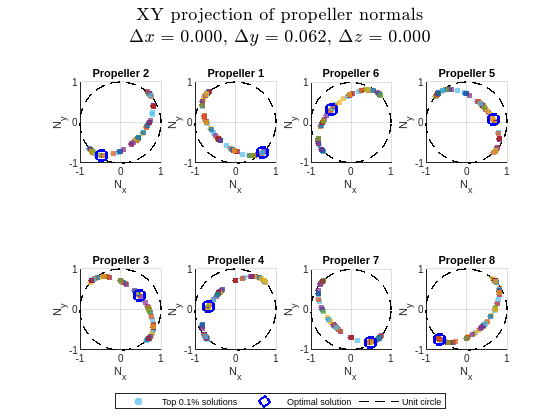

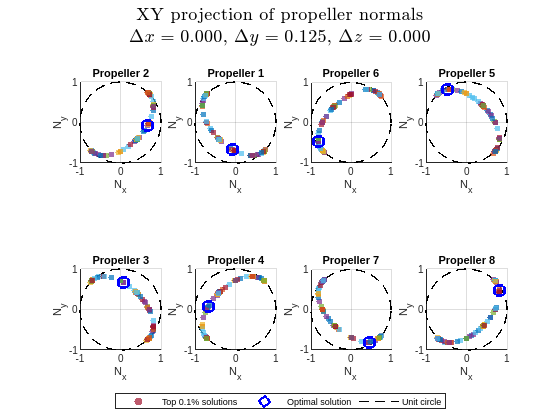

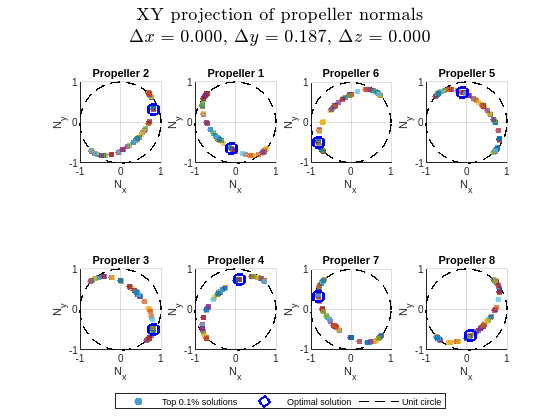

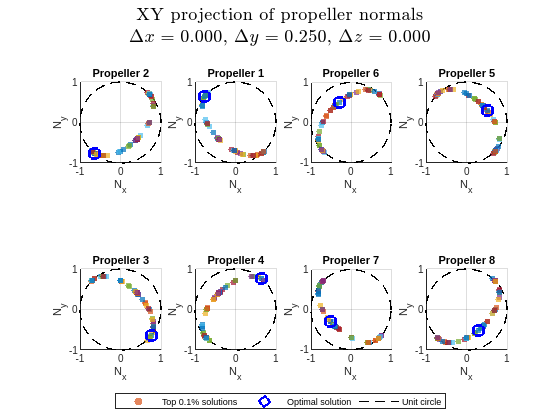

W = 24; H = 14; m = 1.2;

for ic = 1:Ncom
    plotTOP5XY(Results_good, ic);
    fig = gcf;
    dx = CoM_all(1,ic);
    dy = CoM_all(2,ic);
    dz = CoM_all(3,ic);

    titolo = sprintf(['XY projection of propeller normals\n' ...
        '$\\Delta x = %.3f$, $\\Delta y = %.3f$, $\\Delta z = %.3f$'], ...
        dx, dy, dz);
    sgtitle(titolo,'Interpreter','latex','FontSize',14);
    set(fig,'Units','centimeters');
    set(fig,'PaperUnits','centimeters', ...
            'PaperSize',[W H], ...
            'PaperPosition',[m m W-2*m H-2*m]);
    fileName = fullfile(outputFolder, ...
        sprintf('LogVol_Top01_CoM_%02d_%d.pdf', ic, k));
    % print(fig, fileName, '-dpdf','-painters');
    % close(fig);
end

for ic = 1 : 6
    CoM_curr = CoM_all(:, ic);
    N_opt    = Results_good(ic).n; 
    N_opt = N_opt ./ vecnorm(N_opt);
    dx = CoM_curr(1); 
    dy = CoM_curr(2); 
    dz = CoM_curr(3);
    fig = figure('Name', ['Visualizzazione Piani - CoM #' num2str(ic)], ...
           'Color', 'w', 'Units', 'normalized', 'Position', [0 0 1 1]);

    [hCube, hPlane, hOptLine, hCoM] = DroneViewPlanes(pi_B, N_opt, CoM_curr, 45, 45, true);
    titolo = sprintf(['CoM Shift: ' ...
                      '$\\Delta x = %.1f$, $\\Delta y = %.3f$, $\\Delta z = %.1f$)'], ...
                      dx, dy, dz);
    title(titolo, 'FontSize', 14, 'Interpreter', 'latex');
    set(fig, 'PaperUnits','centimeters', 'PaperSize', [W H], ...
             'PaperPosition',[m m W-2*m H-2*m]);
    fileName = fullfile(outputFolder, sprintf('DronePlanes3DLogVol_com_%d_%d.pdf', ic, k));
    % print(fig, fileName, '-dpdf', '-painters');
    % close(fig)
end

### TORUS CHECK

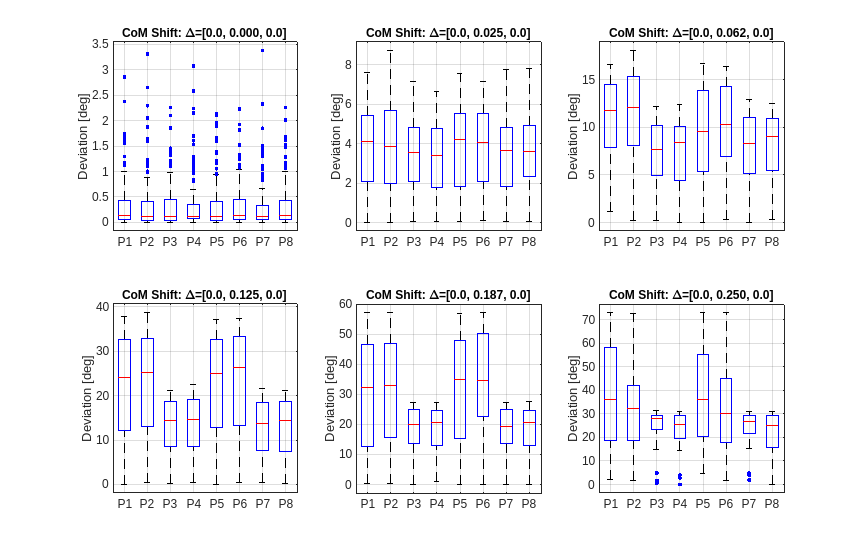

k = 1;
if k == 1
    load(fullfile(resFolder, 'Results_Top01_NoDrag.mat'), 'Results_good');
else
    load(fullfile(resFolder, 'Results_Top01_Complete.mat'), 'Results_good');
end

eps_norm = 1e-12;
nRot = 8;
prop_labels = arrayfun(@(x) sprintf('P%d',x), 1:nRot, 'UniformOutput', false);

Mean_Deviations = nan(Ncom, nRot);
stats = struct([]);
Theta = cell(Ncom,1); 

fig_box = figure('Name', 'Analisi Deviazione per Propeller', 'Color', 'w', ...
    'Units', 'normalized', 'Position', [0 0 1 1]);

fig_hist = figure('Name', 'Analisi Fuori-Piano', 'Color', 'w', ...
    'Units', 'normalized', 'Position', [0 0 1 1]);

for ic = 1:Ncom
    if ic > length(Results_good) || isempty(Results_good(ic).fval)
        stats(ic).Ns = 0; continue;
    end
    Ns = size(Results_good(ic).n, 3);
    if Ns == 0
        stats(ic).Ns = 0; continue;
    end

    dx = CoM_all(1,ic); dy = CoM_all(2,ic); dz = CoM_all(3,ic);   
    p = pi_B_Bcom_all(:,:,ic); 
    rhat = p ./ max(vecnorm(p,2,1), eps_norm); 

    u = zeros(3, nRot); v = zeros(3, nRot); k_hat = [0;0;1];
    for i = 1:nRot
        a = rhat(:,i); 
        if abs(dot(a, k_hat)) > 0.99, ref = [1;0;0]; else, ref = k_hat; end
        u_i = cross(ref, a); u_i = u_i / max(norm(u_i), eps_norm);
        v_i = cross(a, u_i); v_i = v_i / max(norm(v_i), eps_norm);
        u(:,i) = u_i; v(:,i) = v_i;
    end

    dot_abs = nan(Ns, nRot);   
    theta   = nan(Ns, nRot);   
    
    for ksol = 1:Ns
        Nsol = Results_good(ic).n(:,:,ksol);
        Nsol = Nsol ./ max(vecnorm(Nsol,2,1), eps_norm);

        dot_abs(ksol,:) = abs(sum(Nsol .* rhat, 1)); 
        
        cu = sum(Nsol .* u, 1); cv = sum(Nsol .* v, 1);
        th = atan2(cv, cu); th(th < 0) = th(th < 0) + pi; 
        theta(ksol,:) = th;
    end
    
    dev_angles_deg = asin(min(dot_abs, 1)) * 180/pi;

    Mean_Deviations(ic, :) = mean(dev_angles_deg, 1); 
    
    stats(ic).Ns = Ns;
    stats(ic).max_err = max(dot_abs(:));
    stats(ic).mean_err = mean(dot_abs(:));
    max_per_rotore = max(dot_abs, [], 1); 
    Theta{ic} = theta;
    
    % Fig 1
    set(0, 'CurrentFigure', fig_box); 
    subplot(2, 3, ic)
    boxplot(dev_angles_deg, 'Labels', prop_labels, 'Symbol', '.'); 
    grid on; ylabel('Deviation [deg]');
    title(sprintf('CoM Shift: \\Delta=[%.1f, %.3f, %.1f]', dx, dy, dz), ...
          'FontSize', 9, 'Interpreter', 'tex');

    % Fig 2
    set(0, 'CurrentFigure', fig_hist);
    subplot(2, 3, ic)
    histogram(dev_angles_deg(:), 40); 
    grid on; xlabel('Deviation [deg]'); ylabel('Count');
    title(sprintf('CoM Shift: \\Delta=[%.1f, %.3f, %.1f]', dx, dy, dz), ...
          'FontSize', 9, 'Interpreter', 'tex');
    xlim([0, max(5, max(dev_angles_deg(:)))]); 
end
set(0, 'CurrentFigure', fig_box);
annotation('textbox', [0, 1, 1, 0.05], 'String', 'Out of Plane Deviation', ...
           'EdgeColor', 'none', 'HorizontalAlignment', 'center', 'FontSize', 14, 'FontWeight', 'bold');

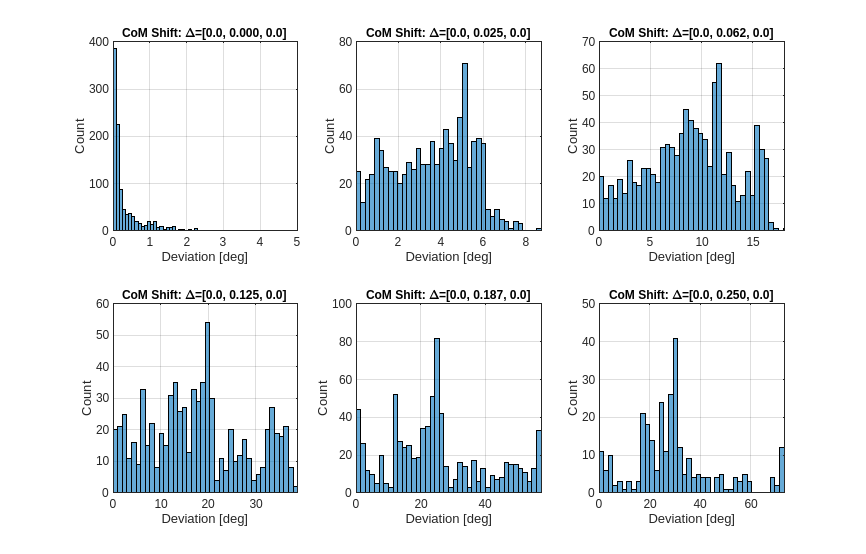

set(0, 'CurrentFigure', fig_hist);
annotation('textbox', [0, 1, 1, 0.05], 'String', 'Out of Plane Distribution', ...
           'EdgeColor', 'none', 'HorizontalAlignment', 'center', 'FontSize', 14, 'FontWeight', 'bold');

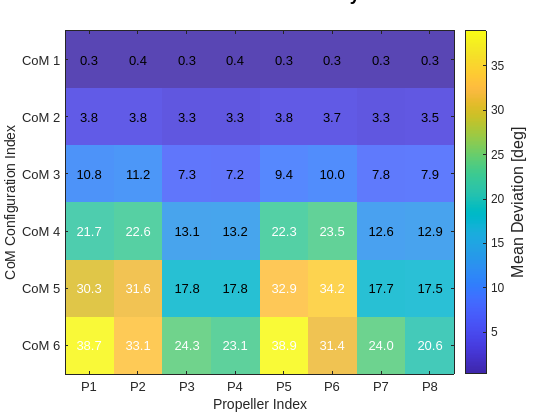


% --- Fig 3
fig_heat = figure('Name', 'Heatmap Sollecitazioni', 'Color', 'w');

h = imagesc(Mean_Deviations);
h.AlphaData = 0.85;  
colormap(parula); 
colorbar;
ylabel(colorbar, 'Mean Deviation [deg]', 'FontSize', 12);
xlabel('Propeller Index');
ylabel('CoM Configuration Index');
set(gca, 'XTick', 1:8, 'XTickLabel', prop_labels);
set(gca, 'YTick', 1:Ncom, 'YTickLabel', arrayfun(@(x) sprintf('CoM %d',x), 1:Ncom, 'UniformOutput', false));
textStrings = num2str(Mean_Deviations(:), '%0.1f');       
textStrings = strtrim(cellstr(textStrings));  
[x_mesh, y_mesh] = meshgrid(1:nRot, 1:Ncom);  
hStrings = text(x_mesh(:), y_mesh(:), textStrings(:), ...  
                'HorizontalAlignment', 'center', 'Color', 'k');
midValue = mean(get(gca, 'CLim'));  
textColors = repmat(Mean_Deviations(:) > midValue, 1, 3);  
set(hStrings, {'Color'}, num2cell(textColors, 2)); 

annotation('textbox', [0, 1, 1, 0.05], 'String', 'Deviation Intensity', ...
           'EdgeColor', 'none', 'HorizontalAlignment', 'center', 'FontSize', 14, 'FontWeight', 'bold');


% --- A
set(fig_box, 'Units', 'centimeters'); 
set(fig_box, 'PaperUnits','centimeters', ...
             'PaperSize', [W H+2], ...
             'PaperPosition',[m m W-2*m H-2*m]);
         
% fileNameBox = fullfile(outputFolder, 'OutofPlane_Boxplot_LogVol.pdf');
% print(fig_box, fileNameBox, '-dpdf', '-painters');

% --- B
set(fig_hist, 'Units', 'centimeters');
set(fig_hist, 'PaperUnits','centimeters', ...
              'PaperSize', [W H+2], ...
              'PaperPosition',[m m W-2*m H-2*m]);

% fileNameHist = fullfile(outputFolder, 'OutofPlane_Histogram_LogVol.pdf');
% print(fig_hist, fileNameHist, '-dpdf', '-painters');

% --- C
set(fig_heat, 'Units', 'centimeters');
set(fig_heat, 'PaperUnits','centimeters', ...
              'PaperSize', [W H], ...
              'PaperPosition',[m m W-2*m H-2*m]);
% fileNameHeat = fullfile(outputFolder, 'OutofPlane_Heatmap_LogVol.pdf');
% print(fig_heat, fileNameHeat, '-dpdf', '-painters');

### PLANE CHECK

prop_labels = arrayfun(@(x) sprintf('P%d',x), 1:nRot, 'UniformOutput', false);

k = 1;
if k == 1
    load(fullfile(resFolder, 'Results_Top01_NoDrag.mat'), 'Results_good');
else
    load(fullfile(resFolder, 'Results_Top01_Complete.mat'), 'Results_good');
end

if k == 1
    load('Results_Top01_Brescianini_LogVol.mat', 'Results_good');
else
    load('Results_Top01_Complete_LogVol.mat','Results_good');
end

PlaneCheck = struct();

for ic = 1:Ncom
    if ic > numel(Results_good) || isempty(Results_good(ic).n)
        continue
    end

    Ns = size(Results_good(ic).n, 3);

    for j = 1:nRot
        % raccogli tutte le normali (unitarie) del propeller j sulle Ns soluzioni
        A = zeros(Ns, 3);
        vPCoM = pi_B_Bcom_all(:,j,ic);   % prop -> CoM
        vPCG  = pi_B(:,j) ;              % prop -> CG
        for ksol = 1:Ns
            nvec = Results_good(ic).n(:, j, ksol);
            nvec = nvec / max(norm(nvec), eps_norm);
            A(ksol,:) = nvec.';
        end

        % Miglior piano passante per origine: min ||A*a|| s.t. ||a||=1
        [~, S, V] = svd(A, 0);
        a = V(:, end);                 % normale del piano
        res = abs(A * a);              % |a^T n_k| = distanza "angolare" dal piano (approx)

        ang_deg = asind(min(res, 1));

        PlaneCheck(ic,j).a = a;
        PlaneCheck(ic,j).smin = S(end,end);     
        PlaneCheck(ic,j).max_deg = max(ang_deg);
        PlaneCheck(ic,j).rms_deg = rms(ang_deg);
        PlaneCheck(ic,j).mean_deg = mean(ang_deg);

        a = a / norm(a);
        
        v1 = vPCoM / max(norm(vPCoM), eps);
        v2 = vPCG  / max(norm(vPCG ), eps);
        
        ang_mod_PCG(ic,j)  = acosd(min(1, abs(dot(a, v2/norm(v2)))));
        ang_mod_PCoM(ic,j) = acosd(min(1, abs(dot(a, v1/norm(v1)))));

    end
end

for ic = 1:Ncom
    max_per_rot = arrayfun(@(j) PlaneCheck(ic,j).max_deg, 1:nRot);
    fprintf('CoM %d: max deviation from best plane per prop [deg] = %s\n', ...
        ic, mat2str(max_per_rot, 3));
end

CoM 1: max deviation from best plane per prop [deg] = [3.99 2.85 2.89 3.75 2.63 3.91 3.18 1.02]
CoM 2: max deviation from best plane per prop [deg] = [2.98 1.09 3.61 3.3 3.07 3.51 3.47 3.73]
CoM 3: max deviation from best plane per prop [deg] = [3.38 4.01 3.49 2.74 3.44 2.19 3.27 3.47]
CoM 4: max deviation from best plane per prop [deg] = [2.37 1.95 3.36 1.11 3.26 3.5 4.24 2.25]
CoM 5: max deviation from best plane per prop [deg] = [3.45 1.49 3.36 1.36 3.84 2.67 3.43 3.34]
CoM 6: max deviation from best plane per prop [deg] = [1.99 1.78 3.24 3.78 4.05 2.94 3.31 4.23]


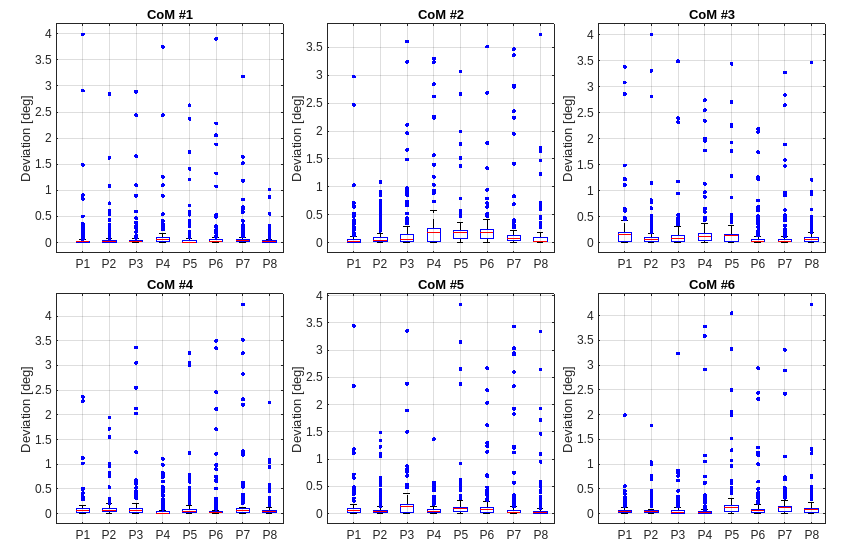

fig = figure('Color','w','Units','normalized','Position',[0 0 1 1]);
tiledlayout(2,3,'TileSpacing','compact','Padding','compact');

for ic = 1:6
    nexttile; hold on; grid on;
    A = []; G = []; 
    
    Ns = size(Results_good(ic).n, 3);
    for j = 1:8
        
        Aj = zeros(Ns,3);
        for ksol = 1:Ns
            nvec = Results_good(ic).n(:,j,ksol);
            nvec = nvec / norm(nvec);
            Aj(ksol,:) = nvec.';
        end
        [~,~,V] = svd(Aj,0);
        a = V(:,end);
        ang_deg = asind(min(abs(Aj*a),1));  % deviazione dal piano in gradi
        
        A = [A; ang_deg(:)];
        G = [G; j*ones(numel(ang_deg),1)];
    end

    boxplot(A, G, 'Labels', prop_labels, 'Symbol','.');
    ylabel('Deviation [deg]');
    title(sprintf('CoM #%d', ic));
end

set(fig, 'Units', 'centimeters');
set(fig, 'PaperUnits','centimeters', ...
              'PaperSize', [W H], ...
              'PaperPosition',[m m W-2*m H-2*m]);
if k == 1
    fileName = fullfile(outputFolder, 'Planes_Box_NoDrag.pdf');
else
    fileName = fullfile(outputFolder, 'Planes_Box_Complete.pdf');
end
% print(fig, fileName, '-dpdf', '-painters');

%% ===== FINAL FIGURE: J_in DISTRIBUTION FOR ALL CoMs (2x3 GRID) =====

deg_thr = 4;
n  = 8;
eps_norm = 1e-12;
Ncom = size(pi_B_Bcom_all, 3);

k  = 1;
if k == 1
    load(fullfile(resFolder, 'All_Results_NoDrag.mat'), 'Results');
else
    load(fullfile(resFolder, 'All_Results_Complete.mat'), 'Results');
end

pi_cg = pi_B_Bcom_all(:,:,1);
rhat = pi_cg ./ max(vecnorm(pi_cg,2,1), eps_norm);

figure('Units','normalized','Position',[0 0 1 0.6]);
tiledlayout(2,3,'TileSpacing','compact','Padding','compact');

for ic = 1:Ncom

    pi_current = pi_B_Bcom_all(:,:,ic);
    Ns = size(Results(ic).N, 3);
    dev_deg = nan(Ns, n);

    for ms = 1:Ns
        Nsol = Results(ic).N(:,:,ms);
        Nsol = Nsol ./ max(vecnorm(Nsol,2,1), eps_norm);

        out = abs(sum(Nsol .* rhat, 1));
        out = min(out, 1);
        dev_deg(ms,:) = asind(out);
    end

    idx_in = max(dev_deg, [], 2) <= deg_thr;
    J_all = Results(ic).fval(:);
    J_in  = J_all(idx_in);

    nexttile;
    grid on; hold on;

    if ~isempty(J_in)
        histogram(J_in, 30, 'Normalization','pdf');
        xline(median(J_in), '--r', 'Median', ...
              'LabelOrientation','horizontal', ...
              'LabelVerticalAlignment','middle');
    else
        text(0.5,0.5,'No solutions in manifold', ...
             'Units','normalized', ...
             'HorizontalAlignment','center');
    end

    title(sprintf('CoM %d', ic));
    xlabel('Objective value J');
    ylabel('pdf');

    fprintf('CoM %d: %d / %d solutions in manifold\n', ic, sum(idx_in), Ns);
end

CoM 1: 146 / 700 solutions in manifold
CoM 2: 141 / 700 solutions in manifold
CoM 3: 150 / 700 solutions in manifold
CoM 4: 135 / 700 solutions in manifold
CoM 5: 131 / 700 solutions in manifold
CoM 6: 115 / 700 solutions in manifold


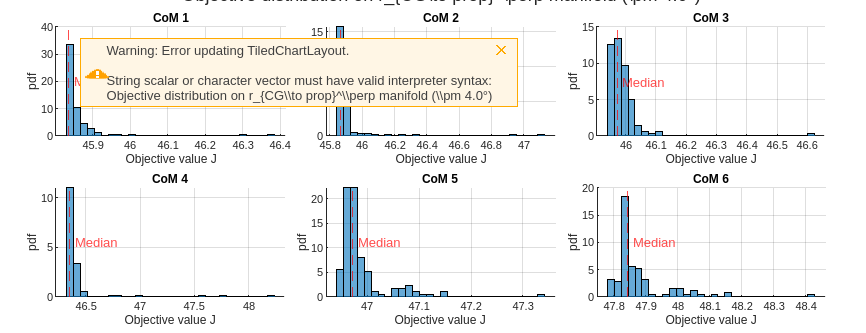


sgtitle(sprintf('Objective distribution on r_{CG\\to prop}^\\perp manifold (\\pm %.1f°)', ...
                deg_thr), ...
        'Interpreter','latex','FontSize',14);

%% ===== Evaluate objective on the manifold: n_j ⟂ pi_cg(:,j) =====
Ns = 500000;           
eps_norm = 1e-12;
eps_obj  = 1e-12;
useUpperHemisphere = true;  % se vuoi forzare n_z>=0

Ncom = size(pi_B_Bcom_all, 3);
n    = size(pi_B_Bcom_all, 2);

% ===== manifold definition uses pi_cg fixed =====
pi_cg = pi_B_Bcom_all(:,:,1);      
[U,V,~] = buildPerpBases(pi_cg, eps_norm);

% ===== Sobol sampling of phi in [0,pi)^n =====
p = sobolset(n,'Skip',1e3,'Leap',1e2);
p = scramble(p,'MatousekAffineOwen');
Phi = pi*net(p, Ns);             

%% Precompute XY coordinates on the manifold (independent of CoM)

Ns = size(Phi,1);
n  = size(Phi,2);

XY = cell(1,n);         
for j = 1:n
    XY{j} = zeros(Ns,2);
end

for s = 1:Ns phi = Phi(s,:); 
    for j = 1:n 
        nj = cos(phi(j))*U(:,j) + sin(phi(j))*V(:,j); 
        if useUpperHemisphere && nj(3) < 0 
            nj = -nj; 
        end 
        
       XY{j}(s,:) = [nj(1), nj(2)]; 
    end 
end

% ===== evaluate objective on manifold for each CoM =====
ManifoldF = struct();

for k = 1:2

    if k == 1
        modelName = 'Brescianini';
    else
        modelName = 'Complete';
    end

    ManifoldF(k).k = k;
    ManifoldF(k).model = modelName;

    for ic = 1:Ncom
        P = pi_B_Bcom_all(:,:,ic);  

        fvals = nan(Ns,1);
        N_store = nan(3,n,Ns);      

        for sidx = 1:Ns
            phi = Phi(sidx,:);

            % build N (3x8) on manifold
            Ntest = zeros(3,n);
            for j = 1:n
                nj = cos(phi(j))*U(:,j) + sin(phi(j))*V(:,j);
                if useUpperHemisphere && nj(3) < 0
                    nj = -nj;
                end
                Ntest(:,j) = nj;
            end

            if k == 1
                B = AllocationMatrixNoDrag(Ntest, P);
            else
                B = AllocationMatrixComplete(Ntest, P);
            end

            svals = svd(B);
            smin  = max(min(svals), eps_obj);
            smax  = max(svals);

            fvals(sidx) = -smin + 10*(smax/smin);
            N_store(:,:,sidx) = Ntest;
        end

        ManifoldF(k).CoM(ic).CoM = CoM_all(:,ic);
        ManifoldF(k).CoM(ic).f   = fvals;
        ManifoldF(k).CoM(ic).N   = N_store;

        [fbest, idxBest] = min(fvals);
        ManifoldF(k).CoM(ic).best.f   = fbest;
        ManifoldF(k).CoM(ic).best.phi = Phi(idxBest,:);
    end

    fprintf('Finished manifold evaluation for model %s\n', modelName);
end

Finished manifold evaluation for model Brescianini
Finished manifold evaluation for model Complete


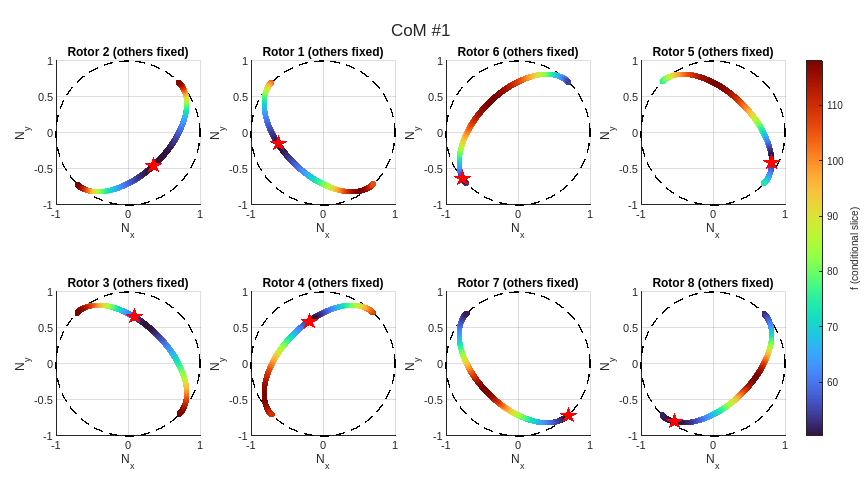

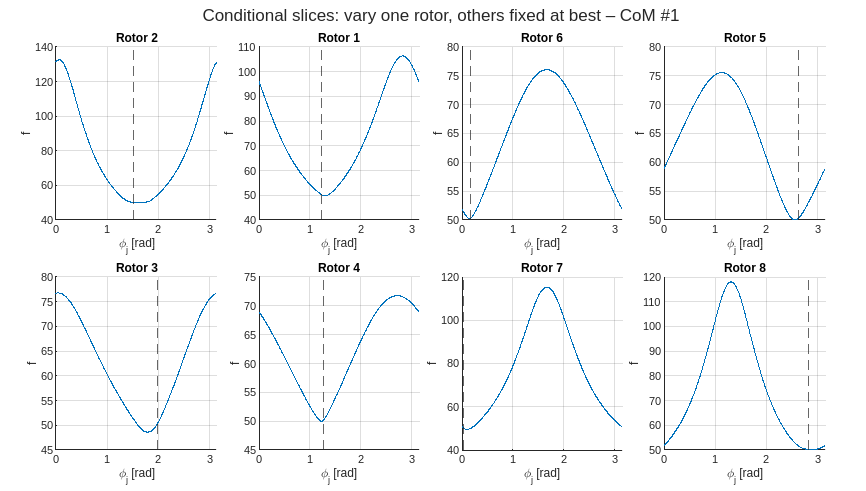

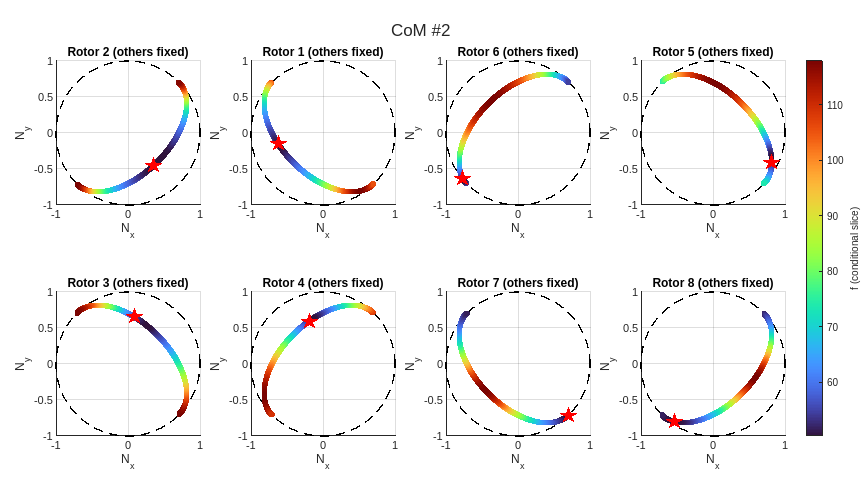

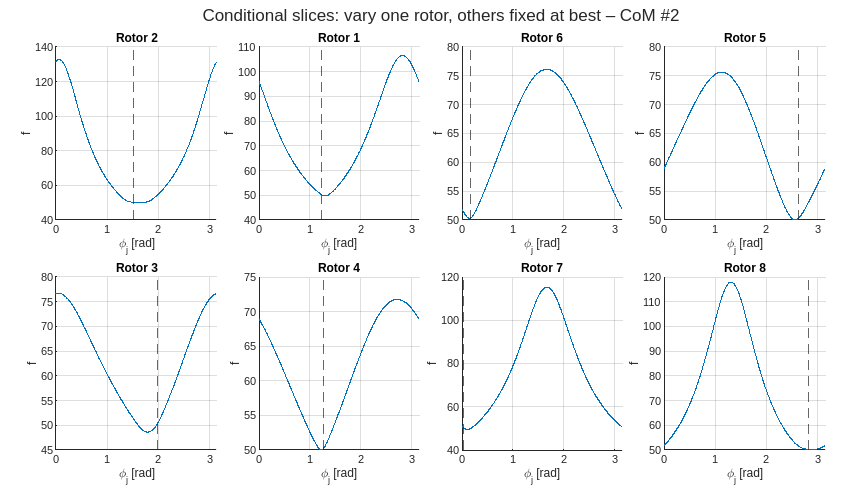

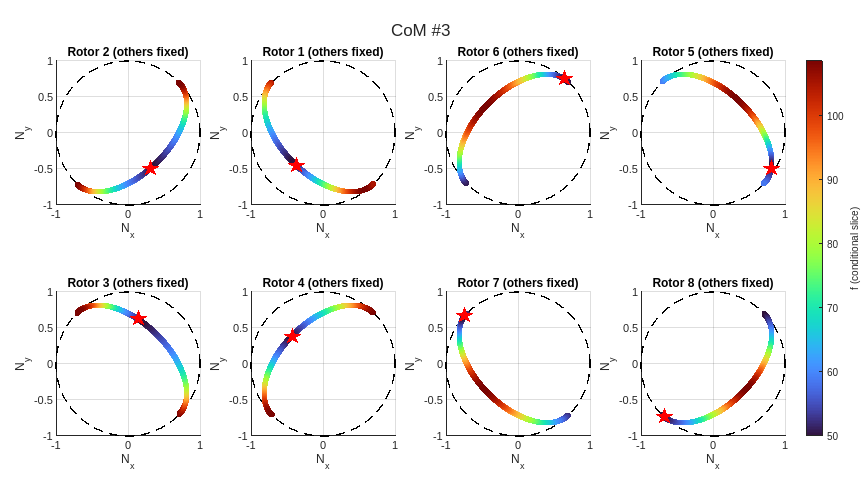

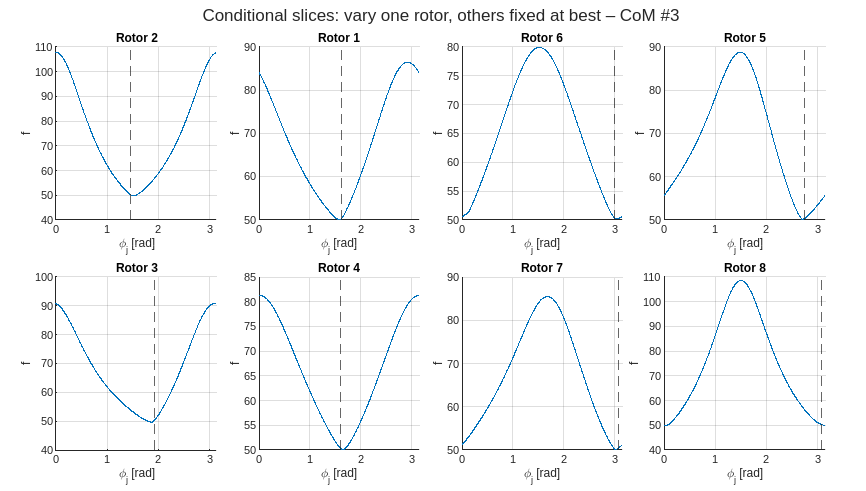

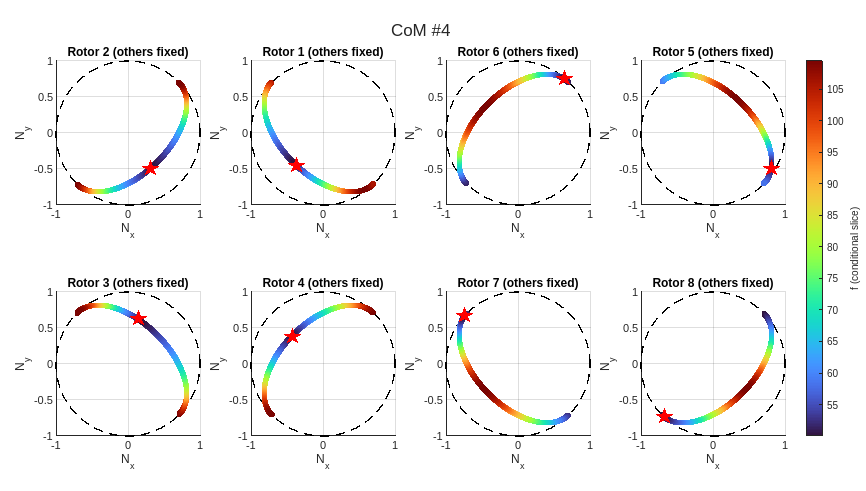

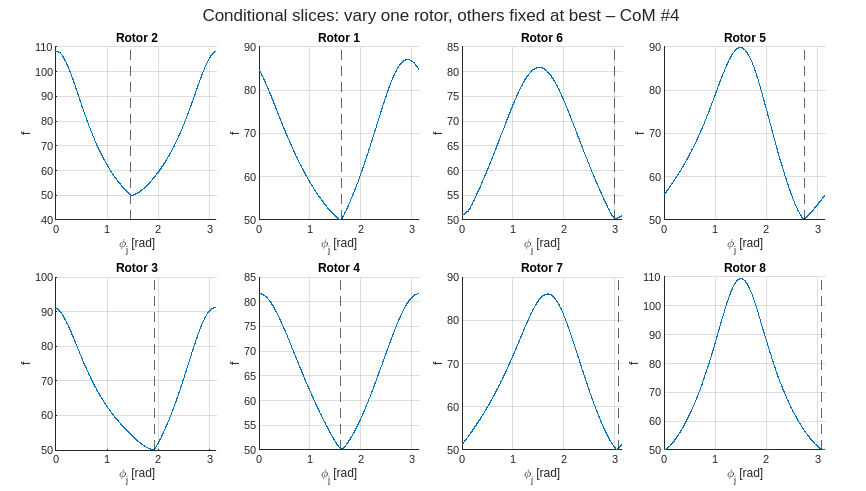

% ===== TOP selection (per k e per ic) =====
topPerc = 0.1;   % in percento per prctile (0.1 = top 0.1%, 10 = top 10%)

for k = 1:2
    for ic = 1:Ncom
        fvals = ManifoldF(k).CoM(ic).f;   

        f_thr = prctile(fvals, topPerc);

        idx_logical = (fvals <= f_thr);       
        idx_ids     = find(idx_logical);      

        ManifoldF(k).CoM(ic).TOP.thr = f_thr;
        ManifoldF(k).CoM(ic).TOP.idx = idx_logical;  
        ManifoldF(k).CoM(ic).TOP.ids = idx_ids;   

        ManifoldF(k).CoM(ic).TOP.f = fvals(idx_logical);
        ManifoldF(k).CoM(ic).TOP.N = ManifoldF(k).CoM(ic).N(:,:,idx_logical); 
    end
end

for k = 1:2
    for ic = 1:Ncom
        Slice = plotConditionalSlicePhi(ManifoldF, pi_B_Bcom_all, ic, k, eps_norm, eps_obj,outputFolder);
    end
end

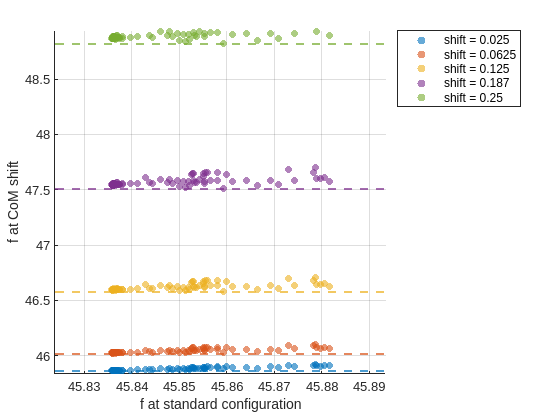

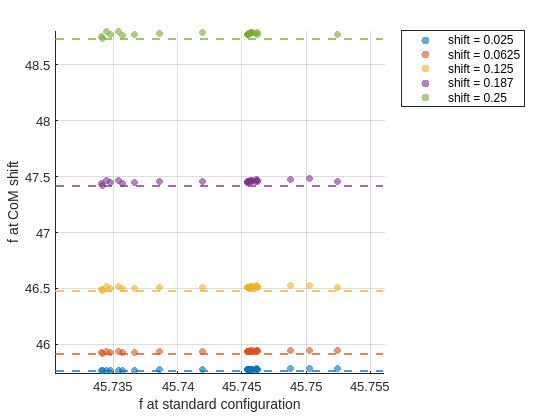


for k=1:2
    Track = trackObjectiveOverCoMShift(k, pi_B_Bcom_all, CoM_all);
    plotFComparisonParity(Track, k, outputFolder);
end


thr = 0.1;  
idxSurvive = cell(1, Ncom);

for ic = 1:Ncom
    idxSurvive{ic} = find(Track.RelF_pct(:,ic) <= thr);
end

for ic = 1:Ncom
    nSurvive(ic) = numel(idxSurvive{ic});
end
